## Integrare numerica

### Suplimentar Hermite

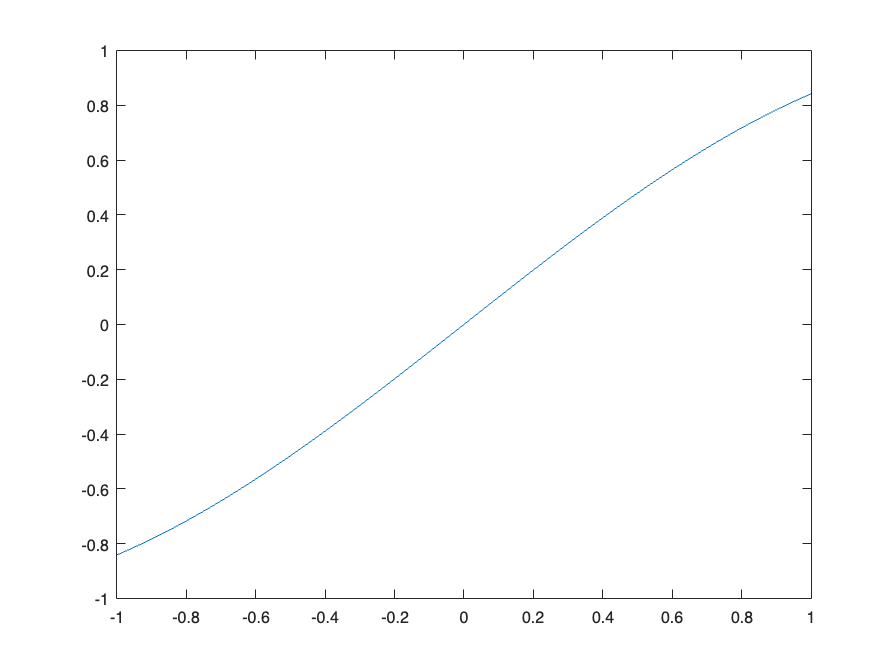

n = 10;
nodes = linspace(-1, 1, n);
f = @(x) sin(x);
y = f(nodes);
syms a
approx = HermitePoly(nodes, ones(n) * 2, a, f(a));
evalPoints = linspace(-1, 1, 300);
plot(evalPoints, subs(approx, a, evalPoints))